clear; clc;

% MATLAB에서 MAT 파일 로드
data = load('0317_2epochedEEG.mat');
epochedEEG = data.epochedEEG; % 1x60 cell (각 cell은 375x16 double)
labels = data.labels; % 60x1 string 배열

% 기본 파라미터 설정
fs = 125; % 샘플링 주파수 (Hz)
num_epochs = length(epochedEEG); % 60개의 에포크
num_channels = size(epochedEEG{1}, 2); % 16채널
num_samples = size(epochedEEG{1}, 1); % 375 샘플

% 밴드패스 필터 생성 (1~40Hz)
[b, a] = butter(4, [1 50] / (fs/2), 'bandpass');

% 필터 적용
filteredEEG = cell(1, num_epochs);
for i = 1:num_epochs
    filteredEEG{i} = filtfilt(b, a, epochedEEG{i});
end

disp('밴드패스 필터링 완료');

밴드패스 필터링 완료


CAR_EEG = cell(1, num_epochs);
for i = 1:num_epochs
    mean_signal = mean(filteredEEG{i}, 2); % 각 샘플에서 평균 계산
    CAR_EEG{i} = filteredEEG{i} - mean_signal; % 평균 신호 제거
end

disp('CAR 변환 완료');

CAR 변환 완료


% 데이터 변환: (375x16x60) → (16x375x60)로 변환
num_trials = length(CAR_EEG);
num_channels = size(CAR_EEG{1}, 2);
num_samples = size(CAR_EEG{1}, 1);

EEG_data = zeros(num_channels, num_samples, num_trials); % (16x375x60) 형태

for i = 1:num_trials
    EEG_data(:,:,i) = CAR_EEG{i}'; % Transpose 필요 (375x16 → 16x375)
end

% 빈 EEG 데이터 생성
EEG = eeg_emptyset(); 

% EEG 데이터 추가
EEG.data = EEG_data; % (16x375x60)
EEG.srate = fs; % 샘플링 주파수 (125Hz)
EEG.nbchan = size(EEG_data, 1); % 16 채널
EEG.trials = size(EEG_data, 3); % 60개의 epoch
EEG.pnts = size(EEG_data, 2); % 375 샘플
EEG.xmin = 0; % 시작 시간 (초)
EEG.xmax = (EEG.pnts - 1) / fs % 종료 시간 (초)

EEG = 다음 필드를 포함한 struct :
             setname: ''
            filename: ''
            filepath: ''
             subject: ''
               group: ''
           condition: ''
             session: []
            comments: ''
              nbchan: 16
              trials: 60
                pnts: 375
               srate: 125
                xmin: 0
                xmax: 2.9920
               times: []
                data: [16×375×60 double]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: []
          urchanlocs: []
            chaninfo: []
                 ref: []
               event: []
             urevent: []
    eventdescription: {}
               epoch: []
    epochdescription: {}
              reject: []
               stats: []
            specdata: []
          specicaact: []
          splinefile: ''
       icasplinefile: ''
              dipfit: []
             history: ''
   

% 채널 위치 파일 불러오기
chanlocs = readlocs('D:\W00Y0NG\PRGM2\MATLAB\eeglab2024.2\sample_locs\Standard-10-20-Cap81.ced', 'filetype', 'chanedit');

Reading file (lines): 10 20 30 40 50 60 70 80 81
readlocs() warning: Fewer columns in the input than expected.
                    See >> help readlocs



% EEG에서 사용할 16개 채널
selected_labels = {'FP1', 'FP2', 'C3', 'C4', 'P7', 'P8', 'O1', 'O2', ...
                   'F7', 'F8', 'F3', 'F4', 'T7', 'T8', 'P3', 'P4'};

% 81개 채널 중에서 16개만 선택
[~, idx] = ismember(selected_labels, {chanlocs.labels});
chanlocs_16 = chanlocs(idx(idx>0));

% EEG에 필터링된 채널 적용
EEG.chanlocs = chanlocs_16;
EEG = eeg_checkset(EEG);

% 적용된 채널 확인
disp(['적용된 채널 개수: ', num2str(length(EEG.chanlocs))]);

적용된 채널 개수: 16


disp({EEG.chanlocs.labels});

    {'FP1'}    {'FP2'}    {'C3'}    {'C4'}    {'P7'}    {'P8'}    {'O1'}    {'O2'}    {'F7'}    {'F8'}    {'F3'}    {'F4'}    {'T7'}    {'T8'}    {'P3'}    {'P4'}



disp('찾은 채널 인덱스:')

찾은 채널 인덱스:


disp(idx)

     1     3    37    41    57    65    74    76    13    21    15    19    35    43    59    63




disp('EEG 데이터 채널 개수:')

EEG 데이터 채널 개수:


disp(size(EEG.data,1)) % EEG 데이터에서 사용할 수 있는 채널 개수 확인

    16



% 채널 개수 확인
disp(['최종 EEG 채널 개수: ', num2str(length(EEG.chanlocs))]);

최종 EEG 채널 개수: 16


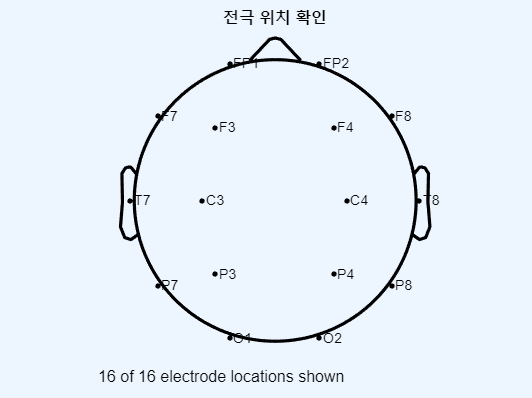


% 전극 위치 시각화
figure;
topoplot([], EEG.chanlocs, 'style', 'blank', 'electrodes', 'labelpoint');
title('전극 위치 확인');

disp(['EEG 데이터 크기: ', num2str(size(EEG.data))]);

EEG 데이터 크기: 16  375   60


disp(['EEG 채널 개수: ', num2str(EEG.nbchan)]);

EEG 채널 개수: 16


disp(['EEG Epoch 개수: ', num2str(EEG.trials)]);

EEG Epoch 개수: 60


disp(['EEG 샘플 개수: ', num2str(EEG.pnts)]);

EEG 샘플 개수: 375


EEG.data = reshape(permute(EEG.data, [1, 3, 2]), EEG.nbchan, []);
EEG.trials = 1;
EEG.pnts = size(EEG.data, 2);
EEG = eeg_checkset(EEG); % 데이터 구조 업데이트

eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames



disp(['변환된 EEG 데이터 크기: ', num2str(size(EEG.data))]);

변환된 EEG 데이터 크기: 16  22500


disp(['변환된 EEG Epoch 개수: ', num2str(EEG.trials)]);

변환된 EEG Epoch 개수: 1


% ICA 실행 (Extended Infomax ICA 사용)
EEG = pop_runica(EEG, 'extended', 1, 'lrate', 0.0001, 'maxsteps', 1000);

Scaling components to RMS microvolt

Saving current ICA decomposition in "EEG.etc.oldicaweights" (etc.).
               Decomposition saved as entry 1.
Attempting to convert data matrix to double precision for more accurate ICA results.
Data rank (15) is smaller than the number of channels (16).

Input data size [15,22500] = 15 channels, 22500 frames/nAfter PCA dimension reduction,
  finding 15 ICA components using extended ICA.
Kurtosis will be calculated initially every 1 blocks using 6000 data points.
Decomposing 100 frames per ICA weight ((225)^2 = 22500 weights, Initial learning rate will be 0.0001, block size 51.
Learning rate will be multiplied by 0.98 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-06 or after 1000 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -1179.42 to 1738.26
Reducing the data to 15 principal dimensions...
Computing the sp

disp('ICA 분석 완료')

ICA 분석 완료


다음 사용 중 오류가 발생함: pop_erpimage (203번 라인)
erpimage of one trial cannot be plotted

Drawing figure...


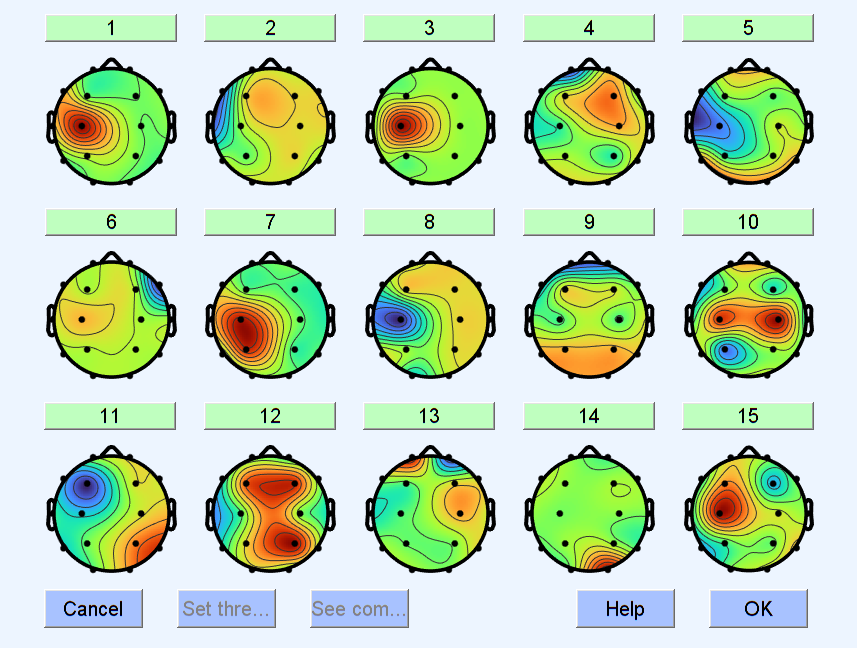

pop_selectcomps(EEG, 1:size(EEG.icawinv, 2));

disp(['EEG.trials: ', num2str(EEG.trials)]);

EEG.trials: 1


disp(['EEG 데이터 크기: ', num2str(size(EEG.data))]); 

EEG 데이터 크기: 16  22500
